Before starting, let's reload our data:

df = readtable("https://raw.githubusercontent.com/trarez/EsameSoftware/main/Nvidia%20Stock%20Prices.csv","VariableNamingRule","preserve");
rng(0, "twister") % for eventual reproducibility

df = df(:, {'Date', 'Adj Close'});
dates = df.Date;
prices = df.("Adj Close");

returns = tick2ret(prices); logreturns = log(1 + returns) * 100;

logReturnsTable = table(dates(2:end), logreturns, 'VariableNames', {'Date', 'logreturns'});

## Heteroskedasticity / Analysis of Volatility 

Let's return to the time series visualization of returns:

figure;
hold on;
patch([dates(1), dates(end), dates(end), dates(1)], [0.3, 0.3, 0, 0], [0.2, 0.8, 0.1], "FaceAlpha", 0.3, "EdgeColor", "none");
patch([dates(1), dates(end), dates(end), dates(1)], [0, 0, -0.2, -0.2], [0.8, 0.1, 0.1], "FaceAlpha", 0.3, "EdgeColor", "none");
plot(dates(2:end), returns);
title("Nvidia Stock Daily Returns (whole period)", "FontSize", 20);
set(gca, "XGrid", "off", "YGrid", "on");
set(gcf, 'position', [10, 10, 2000, 600]);
hold off;

A more interesting phenomenon to analyze in asset returns is its underlying **volatility process**, the process is concerned with the evolution fo conditional variance of the return over time. Usually, periods of high and low volatility are grouped together,. This phenomenon is called **volatility clustering**, which implies the error exhibits time-varying heteroskedasticity, VC can be thus thought as clustering of the variance of the error term over time.

From a financial point of view, the variance of price changes for some asset is a measure of the risk of owning that asset: The larger the variance of daily stock price changes, the more a stock market participant stands to gain, or lose, on a typical day.

It is not possible to use the ARMA models because, even though the conditional mean is time varying, the conditional variance of an ARMA is constant and so these are not able to capture time-varying volatility.

The volatility can be modelled with either (log-)returns squared or (log-)returns in absolute values.

logreturns2 = logreturns.^2; logreturnsAbs = abs(logreturns); % absolute values have the same function of the normal squared ones, they just robustify
                                                              % our transformation, making it less sensible to outliers (used in TSGARCH, for example)
figure
tiledlayout(2,1);
% Tile 1
nexttile
plot(dates(2:end), logreturns2);
set(gca, "XGrid", "off", "YGrid", "on");
set(gcf, 'position', [10, 10, 2000, 600]);
title("Log-returns Squared");
box off;

%tile 2
nexttile
plot(dates(2:end), logreturnsAbs);
set(gca, "XGrid", "off", "YGrid", "on");
set(gcf, 'position', [10, 10, 2000, 600]);
title("Absolute Log-returns");
box off;

Again, we can plot ACF and PACF plots, either for model description and model identification:

figure
tiledlayout(2,1);

% Tile 1
nexttile
autocorr(logreturns2, 'NumLags', 50);
title("ACF for Log-returns Squared")
ylabel(""); xlabel("")
ylim([-0.2, 0.3])
set(gcf, 'position', [10, 10, 2000, 600]);
box off;

%tile 2
nexttile
autocorr(logreturnsAbs, 'NumLags', 50);
title("ACF for Absolute Log-returns")
ylabel(""); xlabel("")
ylim([-0.2, 0.3])
set(gcf, 'position', [10, 10, 2000, 600]);
box off;

In ACFs, it is possible to notice more persistance and correlation among observations, especially for the absolute log-returns.

figure
tiledlayout(2,1);

% Tile 1
nexttile
parcorr(logreturns2, 'NumLags', 50);
title("PACF for Log-returns Squared")
ylabel(""); xlabel("")
ylim([-0.2, 0.3])
set(gcf, 'position', [10, 10, 2000, 600]);
box off;

% Tile 2
nexttile
parcorr(logreturnsAbs, 'NumLags', 50);
title("PACF for Absolute Log-returns")
ylabel(""); xlabel("")
ylim([-0.2, 0.3])
set(gcf, 'position', [10, 10, 2000, 600]);
box off;

We will continue the analysis using the log-returns squared.

Building a volatility modelling for asset (log-)returns consists in four steps, extending the BJ methodology (from *Analysis of Financial Time Series*):

-  specify a mean equation by testing for serial dependence in the data and, if necessary, building an econometric model (e.g., an ARMA model) for the return series to remove any linear dependence;

-  use the residuals of the mean equation to test for ARCH effects;

-  Specify a volatility model if ARCH effects are statistically significant, and perform a joint estimation of the mean and volatility equations.

- . Check the fitted model carefully and refine it if necessary.

### AutoRegressive Conditional Heteroskedasticity (ARCH)

The ARCH is a model proposed by R. Engle in 1982 that describes the variance of the current error term as a function of the actual sizes of the previous time periods' error terms. The model equation is:


$$a_t = \sigma_t \epsilon_t, \quad \sigma_t^2 = \alpha_0 + \alpha_1 a^2_{t-1} + \dots + \alpha_m a^2_{t-m}$$


where $\epsilon_t \sim WN$ and $\alpha_0 > 0 \cup \alpha_i \geq 0 \space \forall i>0$.

From the ARCH framework, it is possible to understand that large shocks tend to be followed by another large shock, thus leading to the modellization of volatility clustering

Volatility models are performed on residuals of the mean equation (ARIMA). The conditional heteroskedasticity is checked by using the squared residuals series. In our case, given that we have chosen not to fit any ARMA model to the (log-)returns, the residuals coincides with the (log-)returns series.

### Properties of ARCH Models

Consider an AR(1) model:


$$a_t = \sigma_t \epsilon_t, \space\space \sigma^2_t = \alpha_0 + \alpha_1 a^2_{t-1}$$


given regularity conditions, the first unconditional mean of a remains zero:


$$E(a_t) = E[E(a_t|F_{t-1})] = E[\sigma_t E(\epsilon_t)]$$


because we hypothesize the error term is a white noise.

The unconditional variance of $a_$ can be obtained as:


$$Var(a_t) = E(a_t^2) = E[E(a_t^2|F_{t-1})] = E(\alpha_t + \alpha_1 a^2_{t-1}) = \alpha_t + \alpha_1 E(a_{t-1}^2) $$


this implies: 


$$Var(a_t) = \frac{\alpha_0}{(1-\alpha_1)}$$


In some applications, we need higher order moments of $a_t$ to exist and $\alpha_t $ must satisfy other constraints.

For instance, to study the tail behaviour, we require that the fourth moment of $a_t$ is finite. Under normality assumptions, considering $F_{t-1}$ the information set available:


$$E(a_t|F_{t-1}) = 3[E(a_t^2|F_{t-1})]^2 = 3(\alpha_0 + \alpha_1 a^2_{t-1})^2 \\ E(a_t^4) = E[E(a^4_t|F_{t-1})] = 3E(\alpha_0 + \alpha_1 a_{t-1}^2)^2 = 3E(\alpha_0^2 + 2 \alpha_0 \alpha_1 a^2_{t-1} + \alpha_1^2 a_{t-1}^4)$$


If $a_t$ is 4-order stationary with $m_4 = E(a_t^2)$, then we have:


$$m_4 = 3[\alpha_0^2 + 2\alpha_0\alpha_1 Var(a_t) + \alpha_1^2 m_4] = 3 \alpha_0^2 \left( 1 + 2\frac{\alpha_1}{1-\alpha_1}\right) + 3\alpha_1^2 m_4$$


hence:


$$m_4 = \frac{3\alpha_0^2(1 + \alpha_1)}{(1-\alpha_1)(1-3\alpha_1^2)}$$


Calculating the unconditional kurtosis of $a_t$ returns:


$$\frac{E(a_t^4)}{[Var(a_t)]^2} = 3 \frac{\alpha_0^2(1 + \alpha_1)}{(1-\alpha_1)(1-3 \alpha_1^2) } \times \frac{(1-\alpha_1)^2}{\alpha^2_0} \\ 
\frac{E(a_t^4)}{[Var(a_t)]^2}  = 3 \frac{1-\alpha_1^2}{1-3 \alpha^2_1} >3$$


The latest inequality is true given $\alpha_1$ must satisfy the condition $\alpha_1$ > 1, as shown before.

This part is important because it tells us the Gaussian ARCH(1) model is more likely than a Gaussian white noise series to produce outlying innovations and hence being leptokurtic. This is fundamental and very helpful in order to model heavy tails, even though in its base version the interval $[0, 1/3]$ is rather restrictive.

These properties hold for every ARCH order and extension [*Analysis of Financial Time Series by Tsai, page 165*].

To assess the presence of ARCH effects, two tests can be used:

- Ljung-Box test (1978), also called **McLeod-Li Test **(1983);

- Engle Lagrange Multiplier Test (1982).

The Ljung-Box test has been explained in the previous live script, so we just perform the iterated statistical test from 1 to 20 lags, either for `logreturnsAbs` and `logreturns2`:

num_lags = (1:20)';
p_values_lb_abs = zeros(20, 1);
p_values_lb_2 = zeros(20, 1);

% Assuming logreturnsAbs and logreturns2 are properly defined or loaded

for lag = 1:20
    % Perform Ljung-Box test on logreturnsAbs
    % [~, p_value_lb_abs] = lbqtest(logreturnsAbs, 'Lags', lag);
    % p_values_lb_abs(lag) = p_value_lb_abs;
    
    % Perform Ljung-Box test on logreturns2
    [~, p_value_lb_2] = lbqtest(logreturns2, 'Lags', lag);
    p_values_lb_2(lag) = p_value_lb_2;
end


results_table = table(num_lags, p_values_lb_abs, p_values_lb_2, ...
                      'VariableNames', {'# of Lags', 'LB p-value for Abs', 'LB p-value for Squared'});

% Display the table
(results_table)

results_table = 20×3 table
    # of Lags    LB p-value for Abs    LB p-value for Squared
    _________    __________________    ______________________

        1                0              2.88713497553772e-12 
        2                0              1.11022302462516e-16 
        3                0                                 0 
        4                0                                 0 
        5                0                                 0 
        6                0                                 0 
        7                0                                 0 
        8                0                                 0 
        9                0                                 0 
       10                0                                 0 
       11                0                                 0 
       12                0                                 0 
  

The null hypothesis of no correlation is strongly rejected in any case.

Just to make sure these zeros are simply extremely low p-values beyond computational feasibility and/or convenience, we run a single test:

[q, p_value, stat, c_value] = lbqtest(logreturnsAbs, Lags = 20)

q = logical
   1


p_value =      0


stat =           1310.73832316851


c_value =           31.4104328442309


#### Engle Lagrange Multiplier Test

An uncorrelated time series can still be serially dependent due to a dynamic conditional variance process. A time series exhibiting conditional heteroscedasticity is said to have ARCH effects.

The test is equivalent to the usual F-test for multiple hypothesis testing, it takes the MLR of the squared residuals (or observations, as we didn't apply any ARIMA or other models) from the mean equation$a_t^2 = \alpha_0 + \alpha_1 a^2_{t-1} + \dots + \alpha_m a^2_{t-m} + e_t \quad t = m+1, \dots, T$ and tests:


$$H_0 : \alpha_i = 0 \quad \forall i \in [1, m] \\
H_1 : \exists \alpha_i \neq 0$$


The test statistic is the *Lagrange Multiplier: *$T \cdot R^2$. Under H0, the asymptotic distribution of the test statistic is $\chi^2(m)$.

The simple search for ARCH effects test in the ARCH(1):

[h, p_value, stat, c_value] = archtest(logreturns)

h = logical
   1


p_value =       2.98694402545152e-12


stat =            48.697191403552


c_value =           3.84145882069413


 We now try to perform the test for ARCH effects up to 20 lags, by iteratively adding residuals squared lags:

num_lags = (1:20)';
p_values_ARCH_Effects = zeros(20, 1);


for lag = 1:20
    % Loop through lags from 1 to 10 and perform the ARCH test
    [~, p_value] = archtest(logreturns, 'Lags', lag);
    p_values_ARCH_Effects(lag) = p_value;
end

results_table = table(num_lags, p_values_ARCH_Effects, ...
                      'VariableNames', {'# of Lags', 'ARCH Effect p-value'});

% Display the table
results_table

results_table = 20×2 table
    # of Lags    ARCH Effect p-value 
    _________    ____________________

        1        2.98694402545152e-12
        2        4.32986979603811e-15
        3         7.7715611723761e-16
        4                           0
        5                           0
        6                           0
        7                           0
        8                           0
        9                           0
       10                           0
       11                           0
       12                           0
       13                           0
       14                           0
       15                           0
       16                           0


If the ARCH effect is statistically significant, it is possible to use the PACF of the logreturns squared to determine the ARCH order, as done when determining the AR order.

figure;
parcorr(logreturns2, "numLags", 50)
title("PACF for log-Returns Squared")
ylabel(""); xlabel("")
ylim([-0.2, 0.3])  %% cut the PACF to visualize better the values
set(gca, "XGrid", "off", "YGrid", "on");
set(gcf, 'position', [10, 10, 2000, 600]);
box off

From visual inspection, it would be interesting to analyze ARCH(1), ARCH(3) and ARCH(5); we will only try with ARCH(3).

%econometricModeler

#### ARCH Estimation

The ARCH estimation is performed by maximizing the log-LL function. If the order of the model is greater than one, then the a joint probability distribution is involved. An interesting point is to eventually hypothesize the errors to be distributed differently than normal. MATLAB permits to define the error distributed as a *t-student* distribution for as many degrees of freedom we want. In financial contexts, as explained before, most of the efforts resides in correctly modeling the tails, and the t-distribution is the first choice beyond the normal one. Below the family tree of distributions:

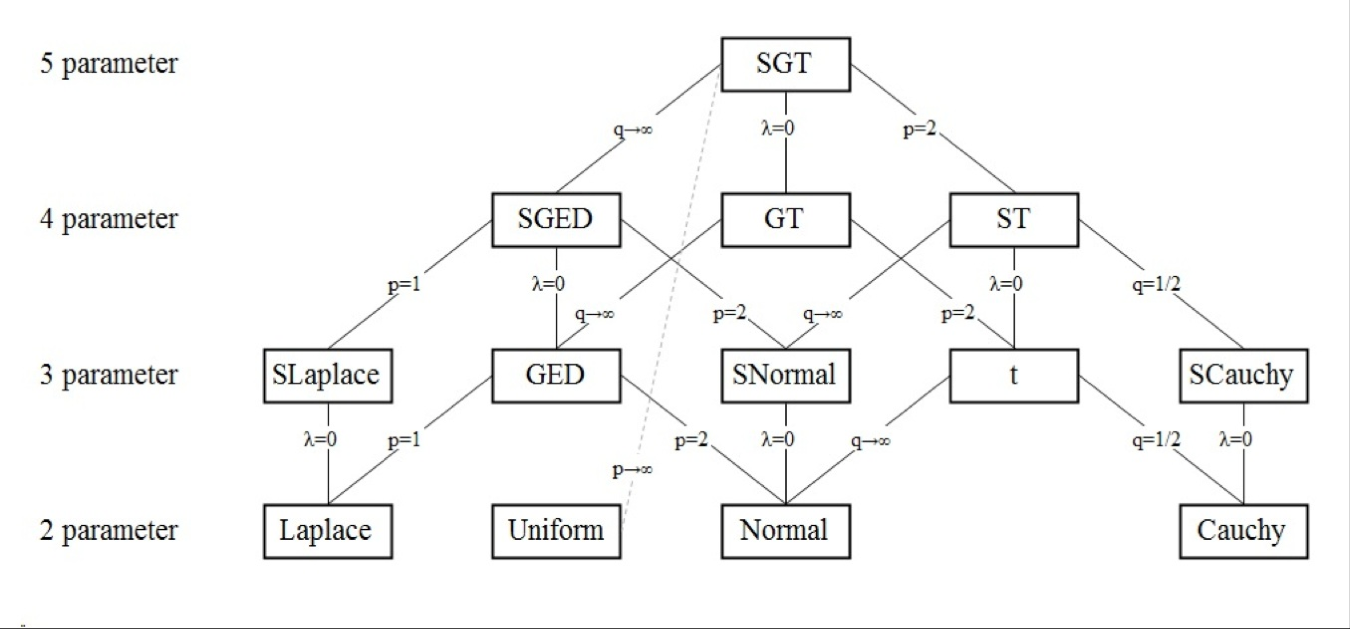

*Image from *[*Skewed generalized t-distribution *](https://en.wikipedia.org/wiki/Skewed_generalized_t_distribution#)Wikipedia page

The ARCH models are estimated and checked two times: one hypothesizing a normal error distribution and the other one a t-student error distribution.

% Specify the ARCH(3) models
ARCH3_g = garch('ARCHLags', 1:3); % g stands for "gaussian"
ARCH3_t = garch('ARCHLags', 1:3, 'Distribution', 't');


estimatedARCH3Model_g = estimate(ARCH3_g, logreturns)

 
    GARCH(0,3) Conditional Variance Model (Gaussian Distribution):
 
                      Value             StandardError          TStatistic              PValue       
                __________________    __________________    ________________    ____________________

    Constant      4.40186058843518    0.0884262602941249    49.7800152781949                       0
    ARCH{1}      0.182067901242428    0.0140526727018778    12.9561048709331    2.16989172937356e-38
    ARCH{2}      0.238989235734351    0.0218015315901218    10.9620388249528     5.8173799412529e-28
    ARCH{3}     0.0956270226470993    0.0112024628658068    8.53624991152443    1.38648307626262e-17



estimatedARCH3Model_g =   garch with properties:

     Description: "GARCH(0,3) Conditional Variance Model (Gaussian Distribution)"
      SeriesName: "Y"
    Distribution: Name = "Gaussian"
               P: 0
               Q: 3
        Constant: 4.40186
           GARCH: {}
            ARCH: {0.182068 0.238989 0.095627} at lags [1 2 3]
          Offset: 0

estimatedARCH3Model_t = estimate(ARCH3_t, logreturns) 

 
    GARCH(0,3) Conditional Variance Model (t Distribution):
 
                      Value            StandardError          TStatistic              PValue       
                _________________    __________________    ________________    ____________________

    Constant     3.77830802360883     0.322160269174475    11.7280384489702    9.15558114193781e-32
    ARCH{1}     0.204871916205987    0.0433581776657537    4.72510440326472    2.29997161295577e-06
    ARCH{2}     0.295191730503291    0.0501591194960858    5.88510590833491    3.97799176986048e-09
    ARCH{3}     0.188348995951191    0.0426101592778631    4.42028378075183    9.85713697816722e-06
    DoF          3.73380558479396     0.272696783274352    13.6921511869742    1.13110271291952e-42



estimatedARCH3Model_t =   garch with properties:

     Description: "GARCH(0,3) Conditional Variance Model (t Distribution)"
      SeriesName: "Y"
    Distribution: Name = "t", DoF = 3.73381
               P: 0
               Q: 3
        Constant: 3.77831
           GARCH: {}
            ARCH: {0.204872 0.295192 0.188349} at lags [1 2 3]
          Offset: 0

All estimates are significant. It is interesting to see the estimated DoF for the second model. A t-distribution becomes a Cauchy distribution if the DoF$v = 1$ and a Normal distribution if Dof $v \rightarrow \infty$.

We can check the AIC/BIC to see whether choosing a more flexible distribution (addition of degrees of freedom parameter) for the innovations has led to improvements:

%% Infering volatility and log-likelihood objective function value from estimated ARCH(3) model
[vG,logLG] = infer(estimatedARCH3Model_g , logreturns); 
[vT,logLT] = infer(estimatedARCH3Model_t ,logreturns);

[aicG, bicG] = aicbic(logLG, 5, length(logreturns)); % 5 parameters for Gaussian model
[aicT, bicT] = aicbic(logLT, 6, length(logreturns)); % 6 parameters for t-distribution model (dof added)

resultsTable = table([logLG; logLT], [aicG; aicT], [bicG; bicT], ...
   'VariableNames', {'LogLikelihood', 'AIC', 'BIC'}, ...
   'RowNames', {'Gaussian', 't-Distribution'})

resultsTable = 2×3 table
                        LogLikelihood            AIC                 BIC       
                      _________________    ________________    ________________

    Gaussian          -7003.10275233586    14016.2055046717    14046.0919146055
    t-Distribution    -6725.92172424671    13463.8434484934    13499.7071404139


Modelling with t-distribution(dof = 3.3) leads to a further $\approx 5\%$ decrease in the information criteria wrt the gaussian distribution for the ARCH(3).

Now the modelling strategies are plotted:

figure;
% tiledLayout(2, 1);

% Tile 1
% nexttile

hold on;
plot(dates(2:end), vT);
plot(dates(2:end), vG);
set(gca, "XGrid", "off", "YGrid", "on");
set(gcf, 'position', [10, 10, 2000, 600]);
title("Comparison t-Distributed vs Gaussian Innovation");
legend({'t-distribution','normal distributed'});
hold off;
box off;

### Generalized ARCH

Even though the ARCH model is simple from a modelling point of view, it often requires many parameters to adequately describe the volatility process of an asset return.

To overcome this, the GARCH has been developed as a ARCH generalization proposed by *Bollerslev *in 1986, as a parsimonious way to characterize ARCH dynamics. 

Given $a_t$ the de-meaned value of our process:


$$a_t = \sigma_t \epsilon_t \space\space\space \sigma_t^2 = \alpha_0 + \sum_{i=1}^p \alpha_i a_{t-i}^2 + \sum_{j=1}^q \beta_j \sigma_{t-j}^2
$$


with $\alpha_0 > 0 \cup \alpha_i \geq 0 \cup \beta_j  \geq 0\space \text{for} j>s.$ The constraint $\sum^{\text{max(m,s})}_{i = 1}\alpha_i + \beta_i < 1$means the unconditional variance of $a_t$ is finite, thus keeping the series covariance-stationary. The conditional variance $\sigma^2_t$ evolves over time.

Setting $\eta_t = a_t^2 - \sigma^2_t, \quad \sigma_t^2 = a_t^2 - \eta_t$ and plugging $\sigma^2_{t-i} = a^2_{t-i} -\eta_{t-1}$ into the previous equation, it is possible to rewrite the GARCH model as:


$$a_t^2 = \alpha_0 + \underbrace{\sum_{i=1}^{m,s} (\alpha_i + \beta_i) a^2_{t-1}}_{\text{AR}} + \eta_t - \underbrace{\sum_{j=1}^{s} \beta_j \eta_{t-j}}_{\text{MA}}$$


essentially an ARMA model for the squared series.

The GARCH(1,1) is specified as follows:

$\text{GARCH(1,1)} :\sigma_t^2 = \alpha_0 + \alpha_1 a_{t-1}^2 + \beta_1 \sigma^2_{t-1}$.

Again, the innovations/errors can hypothesized/modelled as with distributions beyond normal.

In most application, GARCH specification do not go beyond (1,2) or (2,1).

% define the models in a vector
modelNames = ["GARCH11_Gauss", "GARCH11_TDist", "EGARCH11_Gauss", "EGARCH11_TDist", "GJRGARCH11_Gauss", "GJRGARCH11_TDist"];

% pre-allocate vectors for information criteria
aicValues = zeros(1, length(modelNames));
bicValues = zeros(1, length(modelNames));

% store number of observations
T = length(logreturns);


GARCH11_Gauss = garch('Offset',0,'GARCHLags',1,'ARCHLags',1,'Distribution','Gaussian');
[estimatedGARCH11_Gauss, EstParamCov, logL] = estimate(GARCH11_Gauss,logreturns)

 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                      Value             StandardError          TStatistic              PValue       
                _________________    ___________________    ________________    ____________________

    Constant    0.370809643010459     0.0356059740574329    10.4142535859948    2.13465464270468e-25
    GARCH{1}    0.855281001101161    0.00973006059737012    87.9008915250056                       0
    ARCH{1}     0.104433515138277    0.00643753390417488    16.2225965241985    3.49118308983887e-59



estimatedGARCH11_Gauss =   garch with properties:

     Description: "GARCH(1,1) Conditional Variance Model (Gaussian Distribution)"
      SeriesName: "Y"
    Distribution: Name = "Gaussian"
               P: 1
               Q: 1
        Constant: 0.37081
           GARCH: {0.855281} at lag [1]
            ARCH: {0.104434} at lag [1]
          Offset: 0

EstParamCov =        0.00126778538857858     -0.000315898901039253      0.000125381805805935
     -0.000315898901039253      9.46740792284945e-05     -5.12455851284266e-05
      0.000125381805805935     -5.12455851284266e-05      4.14418427674011e-05


logL =          -6932.56082747809


[aicValues(1), bicValues(1)] = aicbic(logL, length(diag(EstParamCov)), T);

GARCH11_TDist = garch('Offset',0,'GARCHLags',1,'ARCHLags',1,'Distribution','t');
[estimatedGARCH11_TDist, EstParamCov, logL] = estimate(GARCH11_TDist,logreturns)

 
    GARCH(1,1) Conditional Variance Model (t Distribution):
 
                      Value              StandardError          TStatistic              PValue       
                __________________    ___________________    ________________    ____________________

    Constant    0.0481043679350355     0.0185526837822338    2.59285225251889     0.00951836515878023
    GARCH{1}     0.942249426077833    0.00773572056791044    121.804997712366                       0
    ARCH{1}     0.0565231625177752    0.00848031791165665    6.66521740182418    2.64273861413465e-11
    DoF           4.01859778169201      0.279694172699633    14.3678280562807    8.23742754020035e-47



estimatedGARCH11_TDist =   garch with properties:

     Description: "GARCH(1,1) Conditional Variance Model (t Distribution)"
      SeriesName: "Y"
    Distribution: Name = "t", DoF = 4.0186
               P: 1
               Q: 1
        Constant: 0.0481044
           GARCH: {0.942249} at lag [1]
            ARCH: {0.0565232} at lag [1]
          Offset: 0

EstParamCov =       0.000344202075523561      -8.9400263181861e-05      3.94020898434442e-05      7.74318084401499e-05
      -8.9400263181861e-05      5.98413727047926e-05     -5.48442883477817e-05     -5.89378425822625e-05
      3.94020898434442e-05     -5.48442883477817e-05      7.19157918827646e-05       -0.0007149831870988
      7.74318084401499e-05     -5.89378425822625e-05       -0.0007149831870988        0.0782288302421323


logL =          -6654.75798919954


[aicValues(2), bicValues(2)] = aicbic(logL, length(diag(EstParamCov)), T);

### E-GARCH

The E(xponential) GARCH is a GARCH extension proposed by D. Nelson in 1991 and revisited by  R. Engle and V. Ng in 1993. 

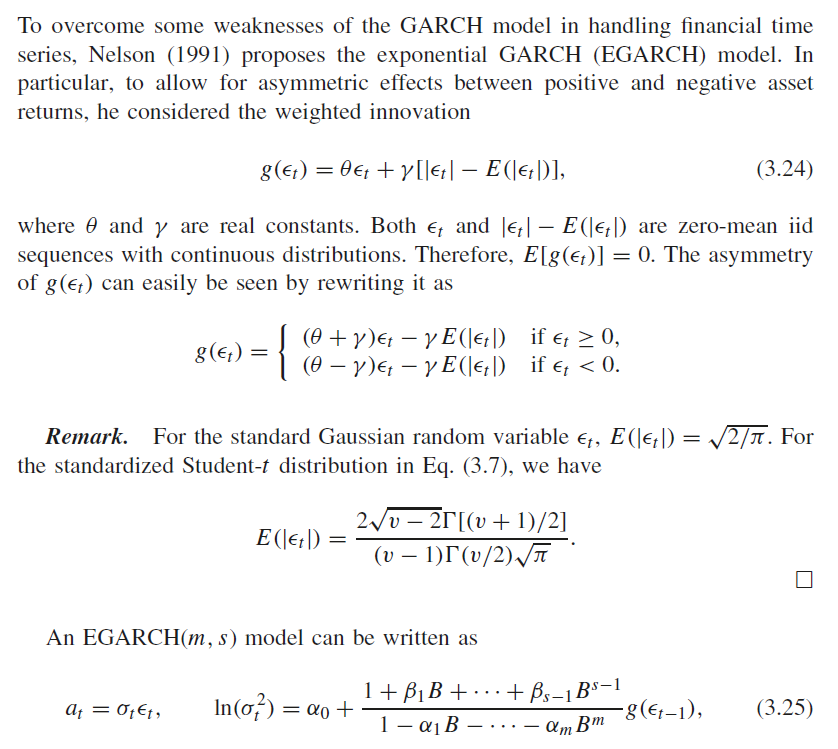

It essentially takes into account the *asymmetry* in the volatility of asset returns. Investors tend to react differently with a negative loss wrt to a positive one. For the former case, more volatility and downturns are generally expected.

Another formulation for this model is:


$$a_t = \sigma_t \epsilon_t, \space\space\space\space \text{EGARCH(s,m):} \space \ln(\sigma_t^2) = \alpha_0 + \sum_{i=1}^s \alpha_1\frac{|a_{t-i}|+ \lambda_1a_{t-1}}{\sigma_{t-1}}  + \sum^m_{j-1}\beta_1 \ln(\sigma_{t-j}^2)
$$


The $\text{ln}(\sigma_t^2)$ conditional variance is used to relax the positiveness constraint of model coefficients.

 A positive $a_{t-1}$contributes $\alpha_i(1 + \lambda_i) |\epsilon_{t-i}|$ to the log volatility, whereas a negative $a_{t-1}$ gives $(1 - \lambda_i) |\epsilon_{t-i}|$, where $\epsilon_{t-i} = a_{t-i}/\sigma_{t-i}$. The $\lambda$ is the *leverage parameter*, the one that actually governs the amount of asymmetricity, expected to be negative.

EGARCH11_Gauss = egarch('Offset',0,'GARCHLags',1,'ARCHLags',1,'LeverageLags',1,'Distribution','Gaussian');
[estimatedEGARCH11_Gauss, EstParamCov, logL] = estimate(EGARCH11_Gauss,logreturns)

 
    EGARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                          Value              StandardError          TStatistic              PValue        
                   ___________________    ___________________    ________________    _____________________

    Constant         0.116091322577065    0.00753086700962318    15.4153993728371      1.2897107019351e-53
    GARCH{1}         0.952551545719573    0.00419120083934702    227.274135082484                        0
    ARCH{1}          0.208675045286715    0.00895997553141318    23.2896891911269    5.63931471864824e-120
    Leverage{1}    -0.0977285140165242    0.00646109534267063    -15.125688266988     1.09648211888857e-51



estimatedEGARCH11_Gauss =   egarch with properties:

     Description: "EGARCH(1,1) Conditional Variance Model (Gaussian Distribution)"
      SeriesName: "Y"
    Distribution: Name = "Gaussian"
               P: 1
               Q: 1
        Constant: 0.116091
           GARCH: {0.952552} at lag [1]
            ARCH: {0.208675} at lag [1]
        Leverage: {-0.0977285} at lag [1]
          Offset: 0

EstParamCov =       5.67139579166308e-05     -3.07082609917695e-05      2.64202018564195e-05       2.1573945896508e-06
     -3.07082609917695e-05      1.75661644757431e-05      -9.3711597601239e-06     -3.00389644045957e-06
      2.64202018564195e-05      -9.3711597601239e-06      8.02811615235229e-05      -6.1876802656566e-06
       2.1573945896508e-06     -3.00389644045957e-06      -6.1876802656566e-06      4.17457530270802e-05


logL =           -6871.5761190858


[aicValues(3), bicValues(3)] = aicbic(logL, length(diag(EstParamCov)), T);

EGARCH11_TDist = egarch('Offset',0,'GARCHLags',1,'ARCHLags',1,'LeverageLags',1,'Distribution','t');

 
    EGARCH(1,1) Conditional Variance Model (t Distribution):
 
                          Value              StandardError          TStatistic               PValue       
                   ___________________    ___________________    _________________    ____________________

    Constant        0.0339500678824557    0.00871133057381059     3.89723103661362    9.72987876914039e-05
    GARCH{1}          0.98462846140597    0.00444998839731543     221.265399703058                       0
    ARCH{1}          0.167569280822102     0.0198911180872457     8.42432688233594    3.62830022972129e-17
    Leverage{1}    -0.0657632854922785     0.0130378126036546    -5.04404285377169    4.55797148017508e-07
    DoF               4.31788990295411       0.31006564155561     13.92

estimatedEGARCH11_TDist =   egarch with properties:

     Description: "EGARCH(1,1) Conditional Variance Model (t Distribution)"
      SeriesName: "Y"
    Distribution: Name = "t", DoF = 4.31789
               P: 1
               Q: 1
        Constant: 0.0339501
           GARCH: {0.984628} at lag [1]
            ARCH: {0.167569} at lag [1]
        Leverage: {-0.0657633} at lag [1]
          Offset: 0

EstParamCov =       7.58872803662071e-05      -3.6376292716571e-05      6.99862452977284e-05     -3.97185901374924e-05      3.09539132579562e-05
      -3.6376292716571e-05       1.9802396736242e-05     -2.85564600029013e-05       1.1533211645724e-05     -0.000179359330052365
      6.99862452977284e-05     -2.85564600029013e-05      0.000395656578760752      -8.4979921764643e-05     -0.000916655410355396
     -3.97185901374924e-05       1.1533211645724e-05      -8.4979921764643e-05      0.000169984557488015      0.000180247893317327
      3.09539132579562e-05     -0.000179359330052365     -0.000916655410355396      0.000180247893317327        0.0961407020732917


logL =          -6622.74040063953


[estimatedEGARCH11_TDist, EstParamCov, logL] = estimate(EGARCH11_TDist,logreturns)
[aicValues(4), bicValues(4)] = aicbic(logL, length(diag(EstParamCov)), T);

### GJR-GARCH

Developed by Glosten, Jagannathan and Runkle in 1993. This model has the same function of the EGARCH, i.e. it tries to capture the asymmetry, but with a different formulation: it uses an *indicator function.*

Another difference with the EGARCH model is that the non-negativity of volatility is guaranteed by parameters constraints, as happens in the normal GARCH model. $\lambda$ is again our average effect.


$$\text{GJR-GARCH(1,1)}:\space \sigma_t^2 = \alpha_0 + \alpha_{t-1}^2 + \lambda_1 S_{t-1} a^2_{t-1} + \beta_1 \sigma^2_{t-1} 
\[
\text{Indicator function: }S_{t-1} = 
\begin{cases} 
1, & \text{if } a_{t-1} < 0; \\
0, & \text{if } a_{t-1} \geq 0.
\end{cases}
\]$$


Also GJR-GARCH has parameter constraints, similar to the GARCH base version.

TGARCH is essentially the same as GJR-GARCH, but it uses absolute residuals instead of squared residuals. We won't use it here, as it is not avaiable in the *econometricModeller.*

GJR11_Gauss = gjr('Offset',0,'GARCHLags',1,'ARCHLags',1,'LeverageLags',1,'Distribution','Gaussian');
[estimatedGJR11_Gauss, EstParamCov, logL] = estimate(GJR11_Gauss,logreturns)

 
    GJR(1,1) Conditional Variance Model (Gaussian Distribution):
 
                         Value             StandardError          TStatistic              PValue       
                   __________________    __________________    ________________    ____________________

    Constant        0.446461289395431    0.0397657783340246    11.2272740054336    2.99578950928799e-29
    GARCH{1}        0.837994243426047    0.0095698847015544    87.5657617160147                       0
    ARCH{1}        0.0418950413915613    0.0058068470378064     7.2147657961019    5.40268807645156e-13
    Leverage{1}     0.167898960507152    0.0121126065392507    13.8615053632823    1.08377261466784e-43



estimatedGJR11_Gauss =   gjr with properties:

     Description: "GJR(1,1) Conditional Variance Model (Gaussian Distribution)"
      SeriesName: "Y"
    Distribution: Name = "Gaussian"
               P: 1
               Q: 1
        Constant: 0.446461
           GARCH: {0.837994} at lag [1]
            ARCH: {0.041895} at lag [1]
        Leverage: {0.167899} at lag [1]
          Offset: 0

EstParamCov =        0.00158131712651078     -0.000342237346414827       3.1525048721924e-05      0.000105245489308799
     -0.000342237346414827      9.15826932010448e-05     -2.31771393983114e-05     -3.44470452412925e-05
       3.1525048721924e-05     -2.31771393983114e-05       3.3719472520481e-05     -2.92362423290804e-05
      0.000105245489308799     -3.44470452412925e-05     -2.92362423290804e-05      0.000146715237174698


logL =          -6906.35888712951


[aicValues(5), bicValues(5)] = aicbic(logL, length(diag(EstParamCov)), T);
GJR11_TDist = gjr('Offset',0,'GARCHLags',1,'ARCHLags',1,'LeverageLags',1,'Distribution','t');
[estimatedGJR11_TDist, EstParamCov, logL] = estimate(GJR11_TDist,logreturns)

 
    GJR(1,1) Conditional Variance Model (t Distribution):
 
                         Value              StandardError          TStatistic              PValue       
                   __________________    ___________________    ________________    ____________________

    Constant       0.0841046479141352     0.0244171450403584    3.44449147413102    0.000572134679378176
    GARCH{1}        0.926160090194914    0.00921629258915191    100.491611050311                       0
    ARCH{1}        0.0286438388969134    0.00755428011144603    3.79173640298472    0.000149597651873213
    Leverage{1}     0.090391741816346     0.0174633293002779    5.17608872066035    2.26585740306367e-07
    DoF              4.27647381251669      0.298603375347435    14.3215856402858    1.

estimatedGJR11_TDist =   gjr with properties:

     Description: "GJR(1,1) Conditional Variance Model (t Distribution)"
      SeriesName: "Y"
    Distribution: Name = "t", DoF = 4.27647
               P: 1
               Q: 1
        Constant: 0.0841046
           GARCH: {0.92616} at lag [1]
            ARCH: {0.0286438} at lag [1]
        Leverage: {0.0903917} at lag [1]
          Offset: 0

EstParamCov =       0.000596196971921901     -0.000151512053583522      2.08254530901804e-05      0.000102497670152629      9.56640104735795e-06
     -0.000151512053583522      8.49400490888565e-05     -3.78227499163725e-05     -7.93740389412283e-05     -0.000117557632704461
      2.08254530901804e-05     -3.78227499163725e-05       5.7067148002189e-05     -2.62376469680464e-05      -0.00037969512266927
      0.000102497670152629     -7.93740389412283e-05     -2.62376469680464e-05      0.000304967870249945     -0.000806547549918936
      9.56640104735795e-06     -0.000117557632704461      -0.00037969512266927     -0.000806547549918936        0.0891639757688812


logL =          -6636.88444397089


[aicValues(6), bicValues(6)] = aicbic(logL, length(diag(EstParamCov)), T);
% Set the display format to avoid scientific notation
format long g

resultsTable = table(modelNames', round(aicValues',3), round(bicValues', 3), ...
    'VariableNames', {'Model', 'AIC', 'BIC'})

resultsTable = 6×3 table
          Model              AIC          BIC   
    __________________    _________    _________

    "GARCH11_Gauss"       13871.122    13889.054
    "GARCH11_TDist"       13317.516    13341.425
    "EGARCH11_Gauss"      13751.152    13775.061
    "EGARCH11_TDist"      13255.481    13285.367
    "GJRGARCH11_Gauss"    13820.718    13844.627
    "GJRGARCH11_TDist"    13283.769    13313.655


To select the "best" model, other than looking for significance in our estimates, we make use of the AIC (*Akaike Information Criterion*) and BIC (*Bayesian Information Criterion*), the two most common types of penalized log-likelihoods.


$$\text{AIC} = 2k - 2\ln(L) \\


\text{BIC} = \ln(T)k - 2\ln(L)$$


 In our case, the model with lowest information criteria is the EGARCH(1,1) with errors distributed as a t-Student(dof = 4.3).

summarize(estimatedEGARCH11_TDist)

 
   EGARCH(1,1) Conditional Variance Model (t Distribution)
 
    Effective Sample Size: 2914
    Number of Estimated Parameters: 5
    LogLikelihood: -6622.74
    AIC: 13255.5
    BIC: 13285.4
 
                          Value              StandardError          TStatistic               PValue       
                   ___________________    ___________________    _________________    ____________________

    Constant        0.0339500678824557    0.00871133057381059     3.89723103661362    9.72987876914039e-05
    GARCH{1}          0.98462846140597    0.00444998839731543     221.265399703058                       0
    ARCH{1}          0.167569280822102     0.0198911180872457     8.42432688233594    3.62830022972129e-17
    Leverage{1}    -0.0657632854922785     0.0

### Model diagnostics

Model diagnostics, or model criticism, is concerned withtesting the goodness of fit of a model and, if the fit is poor, suggesting appropriate modifications.

Even if the EGARCH(1,1) with t-distributed errors turns out to be the relatively "best" model from AIC/BIC point of view, before accepting it for forecasting, it is important to check whether the model is correctly specified, i.e., the model assumptions (about the model errors) are supported by the data.

- *The innovation residuals are uncorrelated*. If there are correlations between innovation residuals, then there is information (patterns) left in the residuals which should be used in computing forecasts.

- *The innovation residuals have zero mean*. If they have a mean other than zero, then the forecasts are biased.

In order to perform these checks, we make use of the *standardized (innovation) residuals. *A correctly specified model present these as i.i.d., to be checked with QQ-plots, normality tests, portmanteau tests.

% Infer residuals and conditional variances
inferredData = infer(estimatedEGARCH11_TDist, logReturnsTable);

Error selecting variables from Tbl1:

Caused by:
    Error using  ()  (line 132)
    Unrecognized table variable name 'Y'.


% Extract residuals and variances from inferred data
residuals = inferredData{:, 'LogReturns_Residual'};
conditionalVariances = inferredData{:, 'LogReturns_Variance'};

Performed with EconometricModeler.

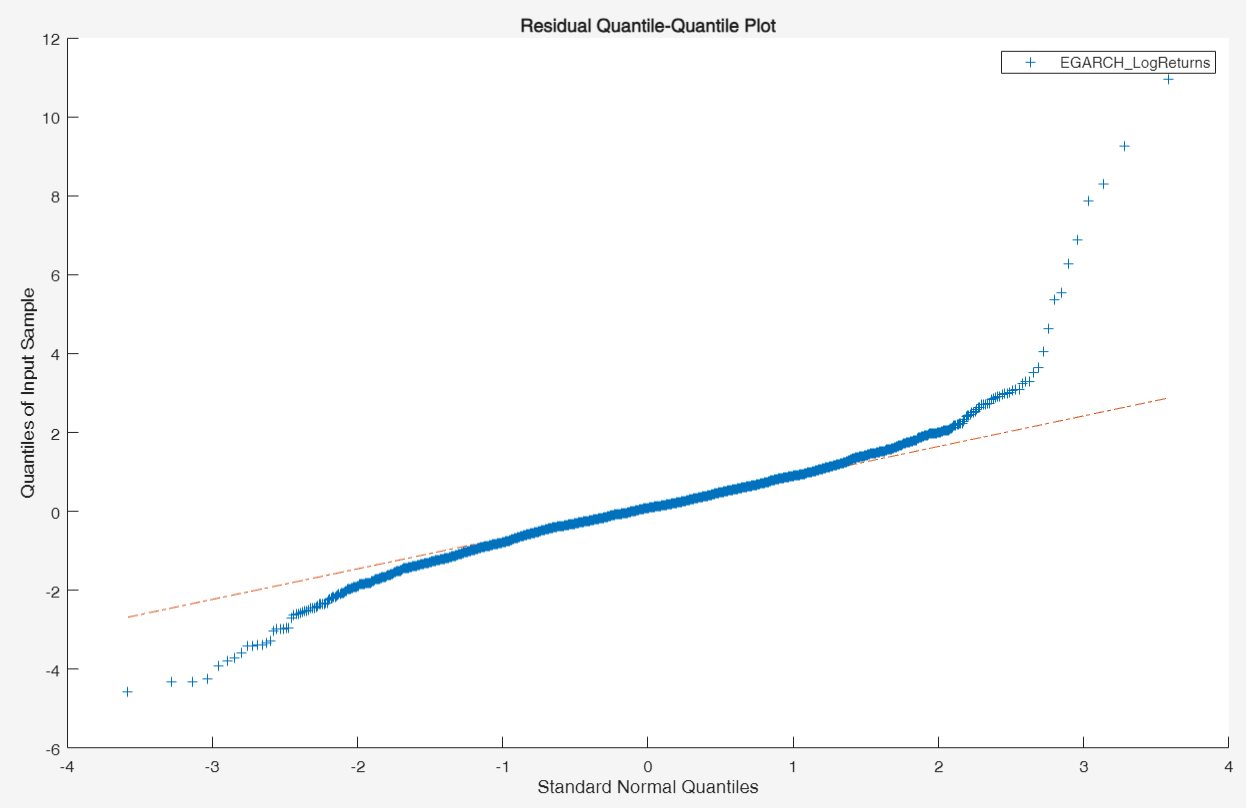 

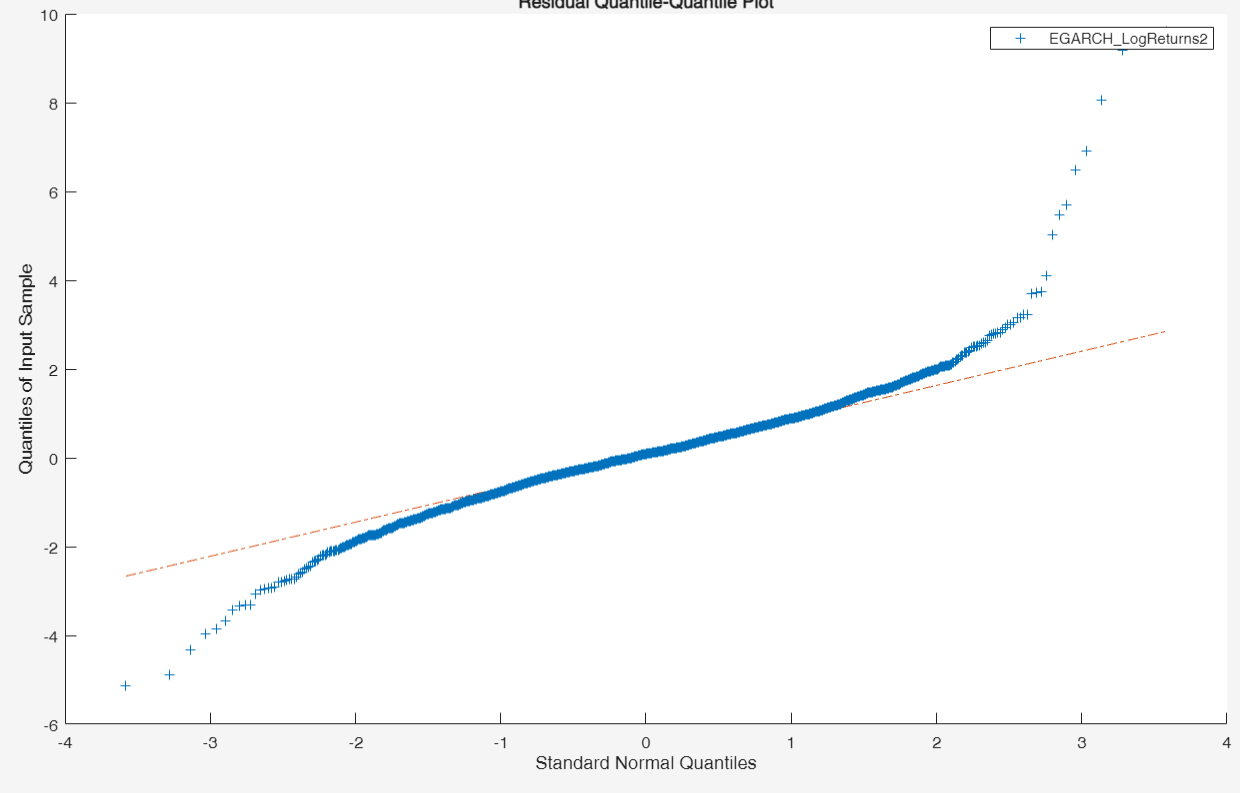

%econometricModeler

### Forecasting

Forecasting the conditional variance of a financial series is of interest for many reasons (from *Introduction to Econometrics, Stock & Watson)*:

- **risk management**: the variance of price changes for some asset is a measure of the risk of owning that asset; the larger the variance of daily stock price changes, the more a stock market participant stands to gain/lose on a typical day. Risk averse investors would be less tolerant in holding volatile asset, and giving them a reasonable forecast could be of great value.

- **financial instrument pricing**: ost of financial derivatives values (such as options) are based on the variance of underlying asset (see *Black-Scholes equations*).

- **efficient estimation**: Forecasting variances can improve the accurary of forecast intervals, If (conditional) heteroskedasticity is present, then the forecast intervals must change accordingly.

When checking predictive performance, it is important not to use the data twice. That is, the data you use to fit your model should be different than the data you use to assess forecasts. You can use *cross-validation* (not in the common way done for cross-sectional data) to evaluate out-of-sample forecasting ability:

- divide your time series into two parts: training set and validation set;

- fit the model to the training data;

- forecast the fitted model over the validation period;

- compare the forecasts to the holdout validation observations using plots and  numerical summaries (such as predictive mean square error).

From $\sigma^2_{t+1}$, denoted as the forecast at time $t +1 $(*one-step ahead forecast*) of the conditional on the history of the process up to time $t$, $H_t$ (in our case our *full information set *available), we can derive the *prediction mean square error (*essentially the MSE, prediction stressed for the time series context), the minimization of the conditional expected square loss:


$$E(\sigma_{t+1} - \hat{\sigma}^2_{t+1}| H_t)$$


Minimizing the loss functions yields the PMSE forecast:


$$\hat{\sigma}^2_{t+1} = E(\sigma^2_{t+1}|H_t) = E(\epsilon^2_{t+1}|H_t)$$


When forecasting beyond $t + 1$, two approaches can be chosen:

- direct estimation, all the $h \text{ in } t+h $ observations are forecasted simultanously using the same parameters;

- iterative estimation, each subsequent observation is forecasted by considering the PMSE of the observation before as a given observation.

The second method is more robust, even though more computationally burdersome. The MATLAB `forecast` function uses this approach.

% create train and test sets with arbitrary trainset ratio (% of
% observations on which we want to train the model)
logReturnsTable = table(dates(2:end), logreturns, 'VariableNames', {'Date', 'logreturns'});
trainRatio = 0.8;
numTrain = ceil(trainRatio * height(logReturnsTable));
%training set
trainWindow = logReturnsTable(1:numTrain, :);

%testing set
testWindow = logReturnsTable(numTrain+1:end, :);

%% test_window = 
specifiedModel = egarch('Offset',0,'GARCHLags',1,'ARCHLags',1,'LeverageLags',1,'Distribution','t');
[estimatedEGARCH11_TDist, EstParamCov, logL] = estimate(specifiedModel, trainWindow.logreturns)

 
    EGARCH(1,1) Conditional Variance Model (t Distribution):
 
                          Value              StandardError          TStatistic               PValue       
                   ___________________    ___________________    _________________    ____________________

    Constant        0.0493126321110316     0.0127151925815833     3.87824500451973    0.000105212729616116
    GARCH{1}         0.975611545005841    0.00694068254728616      140.56420796645                       0
    ARCH{1}          0.194390796408844     0.0257360485664181     7.55324951719653    4.24530557945054e-14
    Leverage{1}    -0.0834146938376809     0.0165174753882907    -5.05008736969658    4.41608038397031e-07
    DoF               3.97442634463845      0.318945967851319     12.46

estimatedEGARCH11_TDist =   egarch with properties:

     Description: "EGARCH(1,1) Conditional Variance Model (t Distribution)"
      SeriesName: "Y"
    Distribution: Name = "t", DoF = 3.97443
               P: 1
               Q: 1
        Constant: 0.0493126
           GARCH: {0.975612} at lag [1]
            ARCH: {0.194391} at lag [1]
        Leverage: {-0.0834147} at lag [1]
          Offset: 0

EstParamCov =        0.00016167612238675     -8.27970018653309e-05       0.00014862646132992     -7.06547389933243e-05     -0.000322610541038068
     -8.27970018653309e-05      4.81730742222027e-05     -6.53572425187247e-05      2.18626860161927e-05     -0.000190386166975921
       0.00014862646132992     -6.53572425187247e-05       0.00066234419581303     -0.000137472531337354      -0.00163978888965693
     -7.06547389933243e-05      2.18626860161927e-05     -0.000137472531337354      0.000272826993202789      0.000581463917612983
     -0.000322610541038068     -0.000190386166975921      -0.00163978888965693      0.000581463917612983         0.101726530408615


logL =          -5109.87482780255


The most basic tool for measuring forecast

% varianceForecast = forecast(estimatedEGARCH11_TDist, numPeriods, 'Y0', logreturns);
% condVar = infer(estimatedEGARCH11_TDist, logrtreturns);
% condVol = sqrt(condVar);
% testWindow
% hold on
% plot(logreturns);
% plot(condVol, 'Color', 'Red', 'LineWidth', 1.2);
% plot(-condVol, 'Color', 'Red', 'LineWidth', 1.2);
% hold off
% set(gca, "XGrid", "off", "YGrid", "on");
% set(gcf, 'position', [10, 10, 2000, 600]);
% box off
% econometricModeler

#### Diebold-Mariano Test

To conclude, [*Forecasting: Principles and Practices*](https://otexts.com/fpp3/toolbox.html) is a good source for learning forecasting, also from a *Modelling of the Modelling Process *point of view (Judgemental Forecasts chapter).